# Neurotech 2021 - Notebook 2: Part 2 (the duece)

## Bayesian Updating

**Sam Michalka - Olin College of Engineering**

## Commentary on this assignment

This notebook is builds upon Notebook 2, Part 1 (shocking, I know). In Part 1, we were introduced to Bayes Theorem and some other rules/laws in probability (which are included below for your reference). 

Here, we explore Bayesian updating. There are multiple ways to approach this notebook, so choose whatever works best for you. You can write the code yourself from scratch, read the writeup that is linked below, and/or work through the guided walkthrough and attempt the exercises.

## Skills and topics

- Bayes Theorem / Bayes Rule

- Bayesian updating

## Resources on Bayes Theorem

Here's the reference for a walkthrough of Bayes Theorem from conditional probabilities: [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading3.pdf](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading3.pdf)  

### Multiplication Rule


$$P\left(A\cap B\right)=P\left(A\left|B\right.\right)\cdot P\left(B\right)$$


### Law of Total Probability

Suppose the sample space Ω is divided into 3 disjoint events $B_1 ,B_2 ,\textrm{and}\;B_3$ (see figure). 

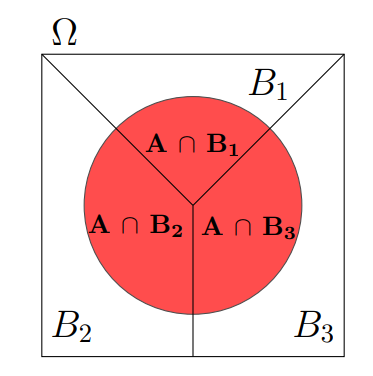

Then for any event A: 


$$P\left(A\right)=P\left(A\left|B_1 \right.\right)\cdot P\left(B_1 \right)+P\left(A\left|B_2 \right.\right)\cdot P\left(B_2 \right)+P\left(A\left|B_3 \right.\right)\cdot P\left(B_3 \right)$$


This just says that the probability of A is just the sum of the probabilities of all those red slices of pie in the figure.

### Independence

Two events A and B are independent if $P\left(A\cap B\right)=P\left(A\right)\cdot P\left(B\right)$.

This is sometimes easier to think about in terms of conditional probabilities:

1) $\textrm{If}\;P\left(B\right)\not= 0,\textrm{then}\;$A and B are independent if, and only if, P(A|B) = P(A).

2) $\textrm{If}\;P\left(A\right)\not= 0,\textrm{then}\;A\;\textrm{and}\;B\;\textrm{are}\;\textrm{independent}\;\textrm{if},\textrm{and}\;\textrm{only}\;\textrm{if},P\left(B\left|A\right.\right)=P\left(B\right)\ldotp$

In other words, knowing that B occurred does not change the probability that A occurred (and vice versa). 

### Bayes' Theorem

Often Bayes Theorem is framed in terms of hypotheses and data, so we'll switch the notation here to use D for data and Hx for some hypothesis x. Importantly, the data stay the same, but we might be evaluating more than one hypothesis.

$P\left(H_x \left|D\right.\right)=\frac{P\left(D\left|H_x \right.\right)\cdot P\left(H_x \right)}{P\left(D\right)}$ or $\textrm{posterior}=\frac{\textrm{likelihood}\cdot \textrm{prior}}{\textrm{marginal}\;\textrm{likelihood}}=\frac{\textrm{Bayes}\;\textrm{Numerator}}{\textrm{marginal}\;\textrm{likelihood}}$

## Bayesian Updating

One of the coolest things about Bayes Theorem is that you can use it iteratively to update your posterior probability as you gain more information. 

The general cycle for this is to: 

- start with some prior (either based on information that you have or a guess, which is often just a uniform distribution if you know nothing)

- calculate your posterior probability using Bayes Theorem

- as you start another round, update your proir to equal your posterior from this round ("yesterday's posterior is today's prior")

We'll now walk through an example that is taken from [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading11.pdf](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading11.pdf) 

You may find it helpful to read through the document first, or you can plow ahead and refer back to it as helpful. 

I suggest that you draw a tree of the starting situation to help organize the information.

There are three types of coins which have different probabilities of landing heads when tossed.

- Type A coins are fair, with probability 0.5 of heads 

- Type B coins are bent and have probability 0.6 of heads 

- Type C coins are bent and have probability 0.9 of heads 

Suppose I have a drawer containing 5 coins: 2 of Type A, 2 of Type B, and 1 of Type C.

We'll now explore a few different scenarios based on this setup. Since there is an optional challenge problem, I'm going to lay out all the scenarios here, but the code and text will provide more scaffolding.

Scenario A:  I reach into the drawer and pick a coin at random. Without showing you the coin, I flip it once and get heads. What is the probability it is Type A? Type B? Type C?

Scenario B: Building on Scenario A, now I flip the same coin again and get heads again. What is the probability that the coin was Type A? Type B? Type C?

Scenario C: Starting over, I reach into the drawer and grab a coin. The coin happens to be Type A, but you don't know this (we'll simulate the results of flipping a fair coin).  What is the probability that the coin was Type A? Type B? Type C? after 10 flips.

Scenario D: You don't know how many of each type of coin there are in my drawer. Imagine I keep flipping the coin and telling you the results (do this by simulating flipping a coin of Type C). Plot the probability of the coin being Type C over each of 40 flips. Repeat this starting from the assumption that the coin is fair (you're completely convinced).

Scenario E:  You don't know anything about the type of coin. (However, you can model it as a finite set of hypotheses. I suggest increments of 0.01.) Choose a probability of heads for your coin and simulate flipping it. Explore how well you can predict the weighting of your coin using Bayes Theorem. How does this compare to keeping a record of the flips and calculating the weight based on the results? 

If you learn best by working through a problem and writing code from scratch, I suggest you try this optional challenge.

#### Optional Challenge: Set up your own code to work through the scenarios described above.

If that sounds overwhelming or not how you like to learn, then try reading along below for a guided tour with a few exercises along the way.

### Guided Tour: Scenario A

Scenario A: Suppose I have a drawer containing 5 coins: 2 of Type A, 2 of Type B, and 1 of Type C. I reach into the drawer and pick a coin at random. Without showing you the coin, I flip it once and get heads. What is the probability it is Type A? Type B? Type C?

First we need to determine what we're trying to find in terms of conditional probabilities. Try to map these out yourself, then read on.

We'll start with the probability that the coin is Type A. The thing we are really interested in is the conditional probability that the coin is Type A given that our first flip was heads:

P(Type == A | Flip 1 == Heads): you might also think of this as P(Hyp | Data) where our hypothesis is coin A and our data is the result of the first flip.  This is our posterior probability (what we're trying to find).

We can determine our prior based on the number of coins in the drawer: P(Type = A) 

We also know the likelihood of heads for each of our coin types P(Flip 1 == Heads | Type == A)

Let's put all of thse Bayes Table (BT) to organize our information and make the calculations easier (doing them for all the rows at once instead of one at a time). This is way to create this table (different than in the last example from a coding standpoint, but gives the same result.

hypothesis = categorical({'A','B','C'})';
prior = [0.4 0.4 .2]';
likelihoodHeads = [0.5 0.6 0.9]';
BT = table(hypothesis,prior,likelihoodHeads);
clear hypothesis prior likelihoodHeads %this just clears the listed variables but leaves everything else
BT

Since we know our coin toss was heads, we can calculate the Bayes Numerator like so:

BT.bayesnumerator = BT.prior .* BT.likelihoodHeads

And then calculate the posterior by dividing the Bayes Numerator by the sum of all the Bayes Numerators. This is the same as dividing by P(Data) or P(Flip 1 == Heads). This is computed using the law of total probability.


$$P\left(\textrm{Flip1}==\textrm{Heads}\right)=P\left(\textrm{Flip1}==\textrm{Heads}\left|\;\textrm{Type}==A\right.\right)\cdot P\left(\textrm{Type}==A\right)+P\left(\textrm{Flip1}==\textrm{Heads}\left|\;\textrm{Type}==B\right.\right)\cdot P\left(\textrm{Type}==B\right)+P\left(\textrm{Flip1}==\textrm{Heads}\left|\;\textrm{Type}==C\right.\right)\cdot P\left(\textrm{Type}==C\right)$$


If you want another explanation of this, check out page 3 of  [https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading11.pdf](https://ocw.mit.edu/courses/mathematics/18-05-introduction-to-probability-and-statistics-spring-2014/readings/MIT18_05S14_Reading11.pdf) 

BT.posterior = BT.bayesnumerator ./ sum(BT.bayesnumerator)

We can also represent this as a graph. We'll use a stem plot, since these are discrete data (you can also use the plot function without the connecting lines to represent discrete data plot(x,y,'o')).

% Plot the posterior probabilities
stem(BT.likelihoodHeads,BT.posterior,'LineWidth',2); axis([0 1 0 1]);
xlabel('Likelihood Heads for Coins A, B, and C'); ylabel('P(Hypothesis | Data)');

### Guided Tour: Scenario B

Scenario B: Building on Scenario A, now I flip the same coin again and get heads again. What is the probability that the coin was Type A? Type B? Type C?

Now it's time for the fun updating part of Bayes... hold on to your drawer full of bent coins!

#### Exercise 1: Repeat the cycle above to find the updated probabilities of each coin type given that you flipped the same coin again and got heads.

% Put your code here.



Hint: What should your prior be going into the next coin flip?

If you get stuck on this, you can move on to the next scenario for answers.

### Guided Tour: Scenario C

Scenario C: Starting over, I reach into the drawer and grab a coin. The coin happens to be Type A, but you don't know this (we'll simulate the results of flipping a fair coin).  What is the probability that the coin was Type A? Type B? Type C? after 10 flips.

We're starting over, so let's clear our workspace and build our table again. Since we're now entertaining the possiblity of flipping a coin and getting tails, I'm going to make a second likelihood option (likelihoodTails). It's not necessary to put this into the table, but it might make it easier to see everything.

clear
hypothesis = categorical({'A','B','C'})';
prior = [0.4 0.4 .2]';
likelihoodHeads = [0.5 0.6 0.9]';
likelihoodTails = 1-likelihoodHeads;
BT = table(hypothesis,prior,likelihoodHeads, likelihoodTails);
clear hypothesis prior likelihoodHeads likelihoodTails 

The code below simulates flipping a coin, printing the results, calculating the appropriate Bayes numerator and posterior probability, updating the plot with the new posteriors, then updating the prior probability for the next round of flipping.

#### Exercise 2: In the code below, fill in the appropriate code for the Bayes numerator for each of the two possible coin flip results.

After you fill in the correct calculations, watch the code run. Make sure you scroll down so you can see the plot update with each flip.

You may also want to explore different coin types and numbers of flips to make sure things are working as you expect and to build some inuition around the plots.

Coin flip #1 is heads 


Coin flip #2 is heads 


Coin flip #3 is heads 


Coin flip #4 is heads 


Coin flip #5 is tails 


Coin flip #6 is tails 


Coin flip #7 is tails 


Coin flip #8 is heads 


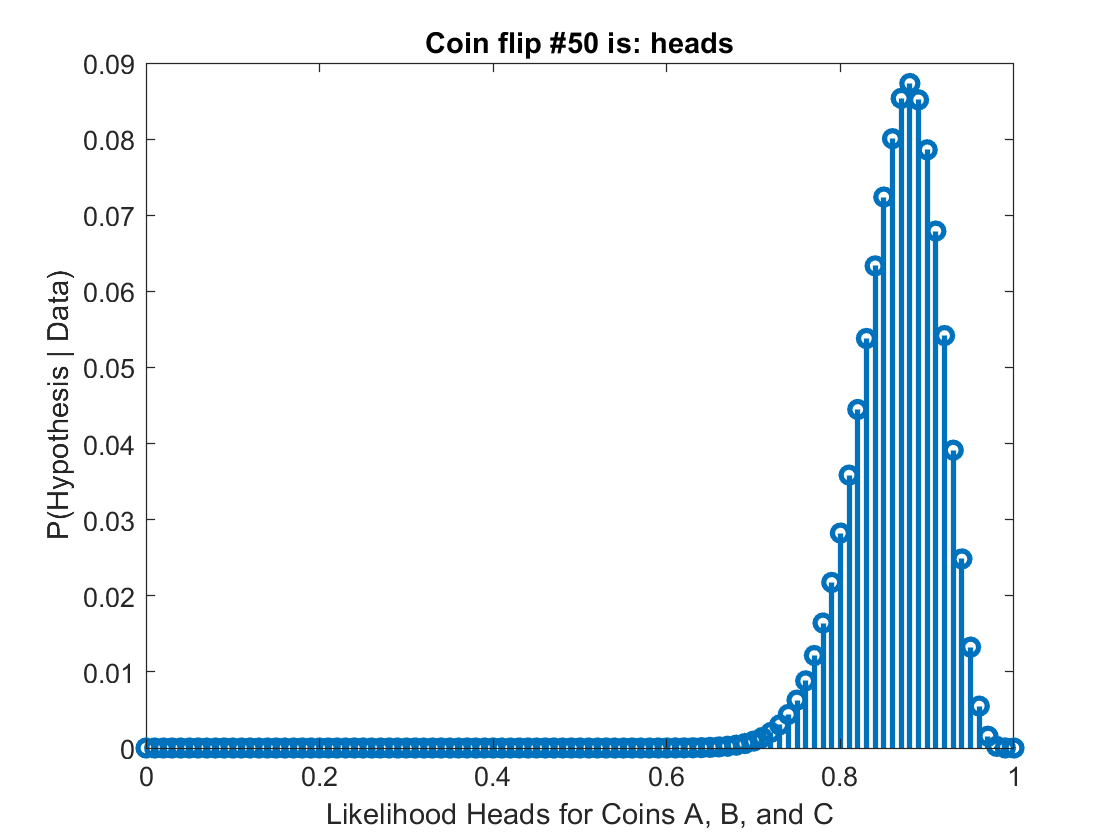

coinoptions = categorical({'tails','heads'});
actualCoinProbHeads = 0.5; % Use this to set the probability of heads for the coin
numFlips = 10; % Use this to determine how many times the coin should be flipped

% Loop through the number of flips
for i = 1:numFlips
    % Flip a coin and print out the results
    coin = coinoptions(1+(rand(1)<=actualCoinProbHeads)); 
    fprintf('Coin flip #%i is %s \n',i,coin)
    
    % Exercise: fill in the appropriate code for the bayes numerator
    % depending on the results of the coin flip
    if coin == "heads"
        BT.bayesnumerator = []; %Put your code here. Leave a semicolon at the end
    elseif coin == "tails"
        BT.bayesnumerator = []; %Put your code here. Leave a semicolon at the end
    end
    
    % Calculate the posterior by normalizing the bayes numerator
    BT.posterior = BT.bayesnumerator ./ sum(BT.bayesnumerator);
    
    % Plot the posterior probabilities
    stem(BT.likelihoodHeads,BT.posterior,'LineWidth',2); axis([0 1 0 1]);
    xlabel('Likelihood Heads for Coins A, B, and C'); ylabel('P(Hypothesis | Data)');
    
    % Pause and then go on to the next round
    pause(3)
    % Update the prior to be the old posterior 
    BT.prior = BT.posterior;
end

### Guided Tour: Scenario D

Scenario D: You don't know how many of each type of coin there are in my drawer. Imagine I keep flipping the coin and telling you the results (do this by simulating flipping a coin of Type C). Plot the probability of the coin being Type C over each of 40 flips. Repeat this starting from the assumption that the coin is fair (you're completely convinced).

Scenario D brings 2 new things to the talbe: 

- not knowing how many of each type of coin there are in the drawer to start (but still knowing that there are only 3 types of coins possible)

- making a plot to show the change in probability as each flip happens.

I suggest that you sketch out what this plot should look like (perhaps on paper). You are welcome to write the code yourself from scratch, or you can use the code that I've provided below and make sure you understand what's happening.

The starting code below starts the same as the code from the previous example, but instead plots the probability of each coin type over time. You can run this and make sure you understand the plot.

#### Exercise 3: Update the code below to reflect that you don't know how many of each type of coin there are in the drawer to start. Describe what happens to the plot over time.

#### Exercise 4: Repeat this starting from the position that you are certain that the coin is fair. Describe what happens to the plot over time.

You may also want to play around with other levels of certainty about the coin's fairness.

clear
hypothesis = categorical({'A','B','C'})';
prior = [0.4 0.4 .2]';
likelihoodHeads = [0.5 0.6 0.9]';
likelihoodTails = 1-likelihoodHeads;
BT = table(hypothesis,prior,likelihoodHeads, likelihoodTails);

BT = 3×4 table
    hypothesis    prior    likelihoodHeads    likelihoodTails
    __________    _____    _______________    _______________

        A          0.4           0.5                0.5      
        B          0.4           0.6                0.4      
        C          0.2           0.9                0.1      


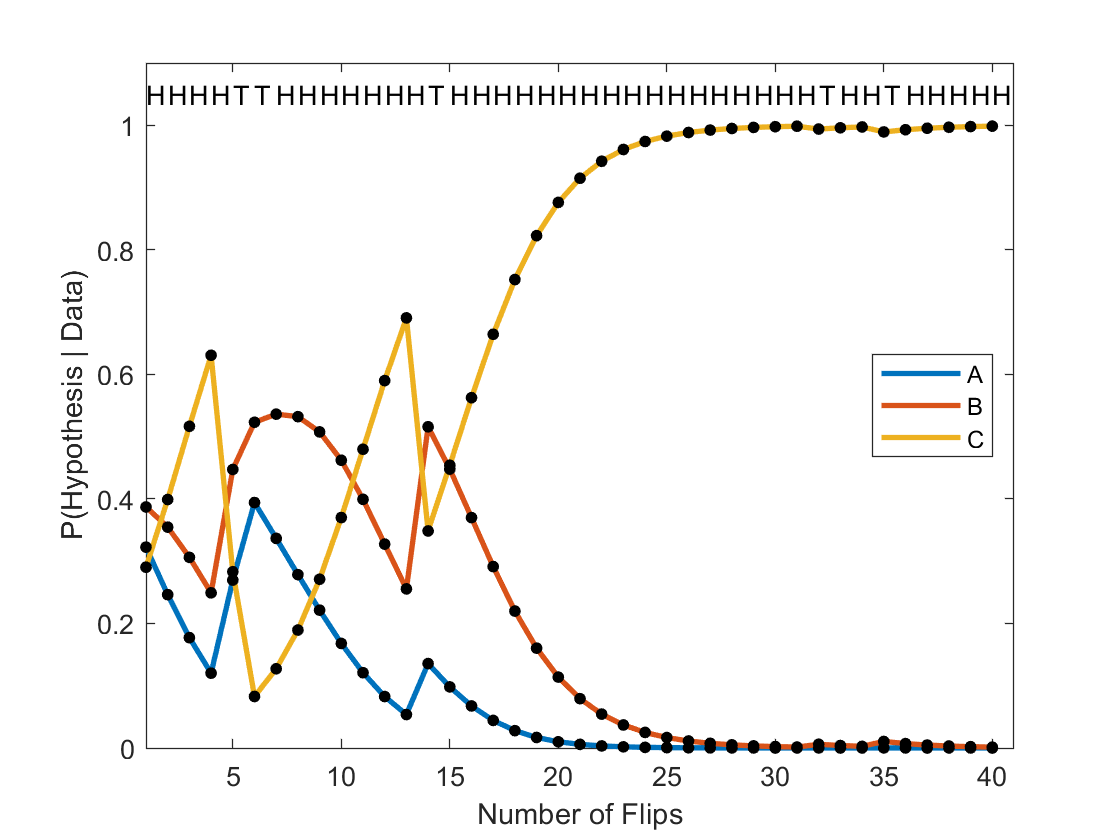

clear hypothesis prior likelihoodHeads likelihoodTails 

coinoptions = categorical({'tails','heads'});
actualCoinProbHeads = 0.9; % Use this to set the probability of heads for the coin
numFlips = 40; % Use this to determine how many times the coin should be flipped

recordFlips = {};
recordPosteriors = zeros(height(BT),numFlips);

% Loop through the number of flips
for i = 1:numFlips
    % Flip a coin and print out the results
    coin = coinoptions(1+(rand(1)<=actualCoinProbHeads)); 
    %fprintf('Coin flip #%i is %s \n',i,coin)
    
    if coin == "heads"
        BT.bayesnumerator = BT.prior .* BT.likelihoodHeads; 
        recordFlips{i} = 'H'; %#ok<SAGROW> 
       
    elseif coin == "tails"
        BT.bayesnumerator = BT.prior .* BT.likelihoodTails; 
        recordFlips{i} = 'T'; %#ok<SAGROW> 
    end
    
    % Calculate the posterior by normalizing the bayes numerator
    BT.posterior = BT.bayesnumerator ./ sum(BT.bayesnumerator);   
    recordPosteriors(:,i) = BT.posterior; %record for plotting
    
    % Plot the posterior probabilities
    pl = plot(1:i,recordPosteriors(:,1:i),'LineWidth',2); axis([1 i+1 0 1.1]);  hold on;
    plot(1:i,recordPosteriors(:,1:i),'k.','MarkerSize',15);
    text(1:i,1.05*ones(1,i),recordFlips(1:i)); 
    xlabel('Number of Flips'); ylabel('P(Hypothesis | Data)'); legend(pl,BT.hypothesis,'Location','East'); hold off;
    
    % Pause and then go on to the next round
    pause(0.1)
    % Update the prior to be the old posterior 
    BT.prior = BT.posterior;
end

### Guided Tour: Scenario E

Scenario E:  You don't know anything about the type of coin. (However, you can model it as a finite set of hypotheses. I suggest increments of 0.01.) Choose a probability of heads for your coin and simulate flipping it. Explore how well you can predict the weighting of your coin using Bayes Theorem. How does this compare to keeping a record of the flips and calculating the weight based on the results? 

In this scenario, we'll go back to the original stem plot style, which we can watch change over time. 

#### Exercise 5: Determine the likelihoodHeads, likelihoodTails, and the prior. Then run the simulation for at least 50 flips and observe the plot.

If you get stuck on how to implement this, just write out how you would like to approach it using words or pseudocode. You can scroll to the end of this notebook to get code that you can copy and paste in.

clear
coinoptions = categorical({'tails','heads'});
actualCoinProbHeads = 0.9;
numFlips = 50;

likelihoodHeads = [];
likelihoodTails = [];
prior = [];



BT = table(prior',likelihoodHeads', likelihoodTails','VariableNames',{'prior','likelihoodHeads','likelihoodTails'}); %The values are transposed here to make the table the right size. If you run into errors about size, you might need to remove the '
clear hypothesis prior likelihoodHeads likelihoodTails 
recordFlips = {};
recordPosteriors = zeros(height(BT),numFlips);

for i = 1:numFlips
    % Flip a coin and print out the results
    coin = coinoptions(1+(rand(1)<=actualCoinProbHeads)); 
    
    if coin == "heads"
        BT.bayesnumerator = BT.prior .* BT.likelihoodHeads;
        recordFlips{i} = 'H'; %#ok<SAGROW>
    else
        BT.bayesnumerator = BT.prior .* BT.likelihoodTails;
        recordFlips{i} = 'T'; %#ok<SAGROW> 
    end
    
    % Calculate the posterior by normalizing the bayes numerator
    BT.posterior = BT.bayesnumerator ./ sum(BT.bayesnumerator);
    recordPosteriors(:,i) = BT.posterior;
    
    % Plot the posterior probabilities
    stem(BT.likelihoodHeads,BT.posterior,'LineWidth',2); xlim([0 1]);
    xlabel('Likelihood Heads for Coins A, B, and C'); ylabel('P(Hypothesis | Data)');
    title(strcat('Coin flip #', num2str(i), ' is: '," ", string(coin)));
    %fprintf('Coin flip #%i is %s ',i,coin)
    % Pause and then go on to the next round
    pause(.5)
    % Update the prior to be the old posterior 
    BT.prior = BT.posterior;
end

#### Exercise 6:  Find the following values after running your simulation

Probability of the coin being double sided heads (always comes up heads)

Probability of the coin being double sided tails (always comes up tails)

Probability of the coin matching whatever you set it to be with actualCoinProbHeads. How would this be different if you only looked at 10 options for coin weightedness/bentness?

The prediction of the weight of the simulated coin (what is the most probable option?)

How does this compare to the value calculated by counting all of the heads and dividing it by the number of total flips (done for you in the following line of code)?

sum(categorical(recordFlips)=='H')./length(recordFlips)

ans = 0.8800

**Challenge**: Investigate the relationship between the number of flips and the accuracy of the prediction

Here is one set of likelihoods and corresponding prior that you can use if you're having trouble.

likelihoodHeads = 0:.01:1; %Likelihood of heads set between 0 and 1, incremented by 0.01
likelihoodTails = 1-likelihoodHeads;
prior = repmat(1/size(likelihoodHeads,2),1,size(likelihoodHeads,2)); % We need the prior to sum to 1 since this covers all possible options.
sum(prior)